% house keeping
clear
% load file
cd("Z:\ting\shared_ting\Yifei\Local Recordings")
release_data = load_xdf("sub-P002_ses-S001_task-LeanAndReleasePilot2_run-001_eeg.xdf")

release_data = 1×3 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}


EEG_channels = release_data{1, 1};
trigger_markers = release_data{1, 2};
num_markers = floor(length(trigger_markers.time_stamps));

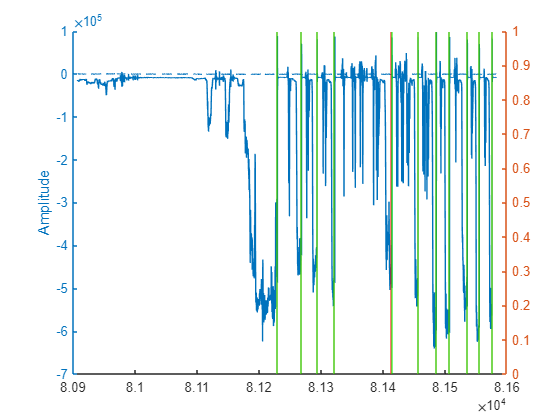

% parameters
channel_force = 33;
channel_acc_x = 41;
grav_acc = 9.80665;
mass = 78; % test usbject's weight is 78kg
window_size = 1000; % the time window for determine the average force sensor read out is 2 sec * 500 Hz = 1000 samples
% test plot
figure
hold on
yyaxis left
plot(EEG_channels.time_stamps, EEG_channels.time_series(channel_force, :))
plot(EEG_channels.time_stamps, EEG_channels.time_series(channel_acc_x, :))
for i = 1 : num_markers
    if mod(i, 2) == 0
        xline(trigger_markers.time_stamps(i), 'g')
    else
        xline(trigger_markers.time_stamps(i), 'r') % 'button press'
%         before_release = trigger_markers.time_stamps(i)
    end
end
ylabel("Amplitude")
hold off

% find the voltage read outs before every trigger button 
force_sensor_readouts_avg_all = zeros(num_markers / 2, 1);
count = 0;
for i = 1 : num_markers
    if mod(i, 2) ~= 0
        count = count + 1;
%         xline(trigger_markers.time_stamps(i), 'r', 'button press')
        index_release = find(EEG_channels.time_stamps >= trigger_markers.time_stamps(i), 1);
        pre_release_window = (index_release - window_size - 5) : (index_release - 5);
        force_sensor_readouts_avg_all(count) = mean(EEG_channels.time_series(channel_force, pre_release_window), 'all');
    end
end

estimated_force_avg_all = (force_sensor_readouts_avg_all / 1e6) * 30 * 0.453592 * grav_acc % in Netwon

estimated_force_avg_all =   -44.7623
  -56.4718
  -56.5058
  -61.0983
  -61.2021
  -67.2444
  -80.4610
  -76.9175
  -68.4317
  -79.1082


estimated_percent_weight_avg_all = abs(estimated_force_avg_all / (mass * grav_acc)) * 100 % in percent body weight

estimated_percent_weight_avg_all =     5.8519
    7.3827
    7.3872
    7.9876
    8.0011
    8.7910
   10.5189
   10.0556
    8.9463
   10.3420


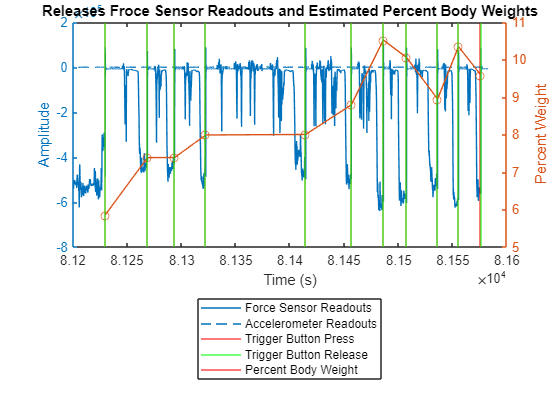

yyaxis right
plot(trigger_markers.time_stamps(1 : 2 : end), estimated_percent_weight_avg_all, '-o')
xlim([8.12e4, 8.16e4])
legend("Force Sensor Readouts", "Accelerometer Readouts", "Trigger Button Press", "Trigger Button Release", "Percent Body Weight", 'Location','southoutside')
ylabel("Percent Weight")
xlabel("Time (s)")
title("Releases Froce Sensor Readouts and Estimated Percent Body Weights")